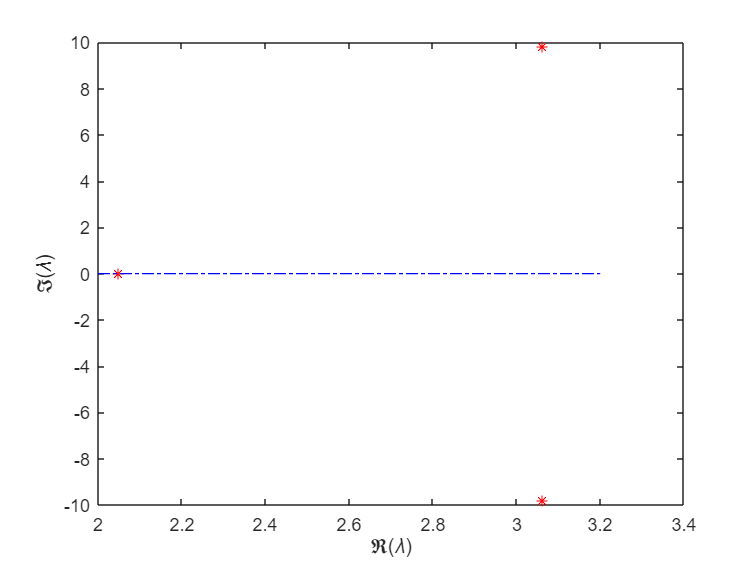

%%
clear;
close all;

addpath('../../../ddebiftool',...
    '../../../ddebiftool_utilities');

% 定义sigmoid函数及其导数
f = @(x, beta) 1./(1 + exp(-beta * x));
df = @(x, beta) beta * f(x, beta) .* (1 - f(x, beta));

% 系统右侧函数
neuron_sys_rhs = @(xx, par) [
    -xx(1,1) + f( par(1)*xx(1,2) + par(2)*xx(2,3) + par(5), par(7) )
    -xx(2,1) + f( par(3)*xx(1,3) + par(4)*xx(2,2) + par(6), par(7) )
];

% 参数顺序: [c1, c2, c3, c4, P, Q, beta, tau1, tau2]
tau_ind = [8, 9]; % tau1和tau2分别对应参数8和9
funcs = set_funcs(...
    'sys_rhs', neuron_sys_rhs,...
    'sys_tau', @() tau_ind,...
    'sys_deri', @neural_deri...
);

%% 初始参数设置
c1 = -1; c2 = -0.4; c3 = -1; c4 = 0;
P = 0.7; Q = 0.5; beta_val = 60;
tau1_val = 0.2; tau2_val = 0.2; % 初始tau值

stst.kind = 'stst';
stst.parameter = [c1, c2, c3, c4, P, Q, beta_val, tau1_val, tau2_val];
stst.x = [0.5; 0.5]; % 初始猜测

%% 校正稳态点
method = df_mthod(funcs, 'stst');
method.stability.minimal_real_part = -0.04;
[stst, success] = p_correc(funcs, stst, [], [], method.point);

%% 计算稳定性
stst.stability = p_stabil(funcs, stst, method.stability);
figure(1); clf;
p_splot(stst);


%% 初始化分支 (P作为分岔参数)
ind_P = 5; % P在参数向量中的位置
branch1 = df_brnch(funcs, ind_P, 'stst');

% 参数范围设置
branch1.parameter.min_bound(1,:) = [ind_P 0.4];
branch1.parameter.max_bound(1,:) = [ind_P 1.0];
branch1.parameter.max_step(1,:) = [ind_P 0.01];

% 扩展分支
branch1.point = stst;
stst2 = stst;
stst2.parameter(ind_P) = stst2.parameter(ind_P) + 0.001;
[stst2, success] = p_correc(funcs, stst2, [], [], method.point);
branch1.point(2) = stst2;

figure(2); clf;
[branch1,~,~,~] = br_contn(funcs, branch1, 300);

BR_CONTN warning: boundary hit.


branch1 = br_rvers(branch1);
[branch1,~,~,~] = br_contn(funcs, branch1, 300);

BR_CONTN warning: boundary hit.


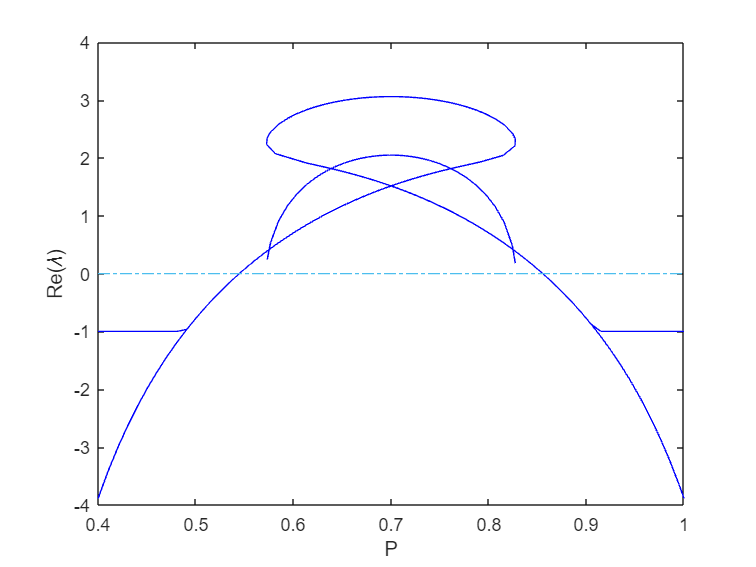


%% 计算分支稳定性
branch1.method.stability.minimal_real_part = -0.01;
branch1 = br_stabl(funcs, branch1, 0, 0);

% 绘制分岔图
[xm, ym] = df_measr(1, branch1);
figure(3); clf;
br_plot(branch1, xm, ym, 'b');
hold on;
plot([0.4 1], [0 0], '-.');
xlabel('P');
ylabel('Re(\lambda)');


%% Hopf分岔分析
hopf_ind = find(arrayfun(@(p) any(real(p.stability.l0) > 0), branch1.point), 1);
hopf = p_tohopf(funcs, branch1.point(hopf_ind));

method = df_mthod(funcs, 'hopf');
[hopf, success] = p_correc(funcs, hopf, ind_P, [], method.point);

% 计算Lyapunov系数
addpath('../../../ddebiftool_extra_nmfm');
hopf = nmfm_hopf(funcs, hopf);
fprintf('First Lyapunov coefficient: %g\n', hopf.nmfm.L1);

First Lyapunov coefficient: -507.228


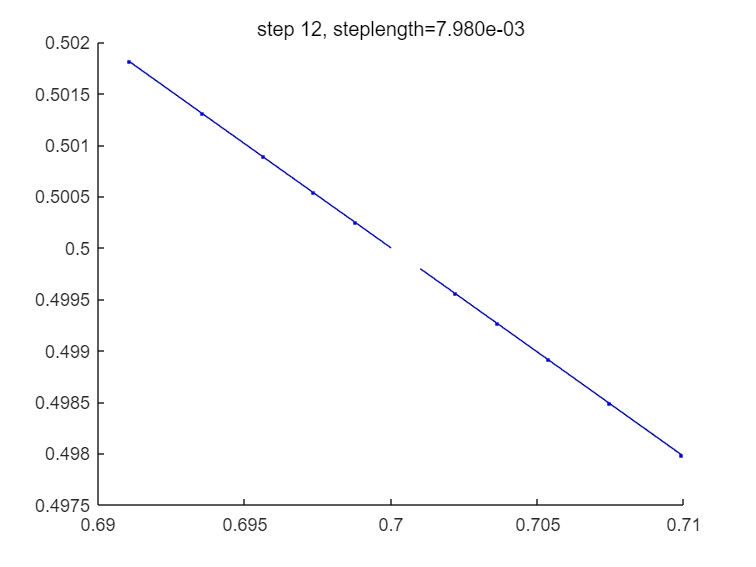

%% 第一部分：P-tau双参数分岔图
% 设置双参数分支
tau_ind = 8; % 选择tau作为第二个参数
branch2 = df_brnch(funcs,[ind_P],'stst');

% 参数范围设置
branch2.parameter.min_bound = [
    ind_P 0.4;
    tau_ind 0;
];
branch2.parameter.max_bound = [
    ind_P 1.0;
    tau_ind 0.5;
];
branch2.parameter.max_step = [ind_P 0.02; tau_ind 0.02];

% 添加初始点
branch2.point = [stst,stst2];

% 延续计算
figure(4); clf;
branch2 = br_contn(funcs,branch2,5);
branch2 = br_rvers(branch2);
branch2 = br_contn(funcs,branch2,5);

% 检测分岔点（新增关键步骤）
branch2

branch2 = 包含以下字段的 struct :
       method: [1×1 struct]
    parameter: [1×1 struct]
        point: [1×12 struct]

br_bifdet(funcs, branch2)

ans = 包含以下字段的 struct :
       method: [1×1 struct]
    parameter: [1×1 struct]
        point: [1×12 struct]

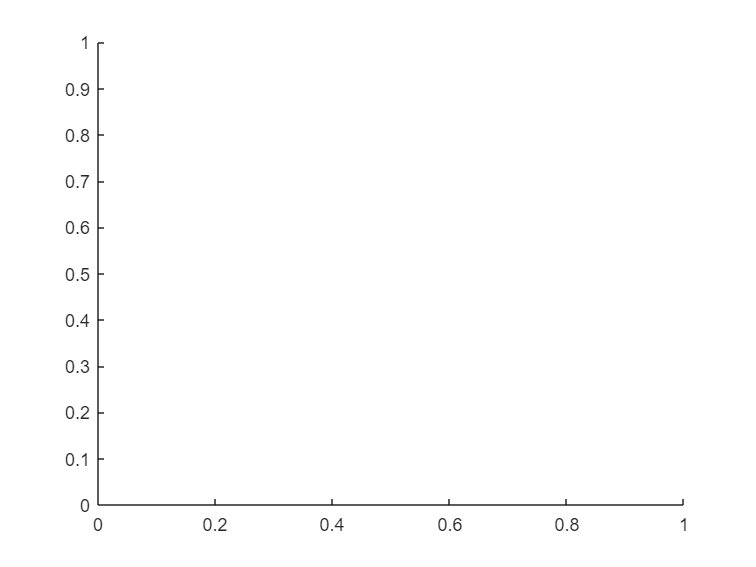

branch2 = br_bifdet(funcs, branch2);
branch2 = br_stabl(funcs,branch2,0,0);

% 提取Hopf和鞍结分岔点
hopf_pts = [];
fold_pts = [];
for i=1:length(branch2.point)
    if ~isempty(branch2.point(i).stability)
        if any(strcmp({branch2.point(i).flag},'hopf'))
            hopf_pts = [hopf_pts; branch2.point(i).parameter(ind_P) branch2.point(i).parameter(tau_ind)];
        elseif any(strcmp({branch2.point(i).flag},'fold'))
            fold_pts = [fold_pts; branch2.point(i).parameter(ind_P) branch2.point(i).parameter(tau_ind)];
        end
    end
end

% 绘制双参数分岔图
figure(5); clf; hold on;

plot(branch2.parameter(ind_P,:), branch2.parameter(tau_ind,:), 'k-', 'LineWidth', 1.5);

位置 1 处的索引超出数组边界。索引不能超过 1。

if ~isempty(hopf_pts)
    plot(hopf_pts(:,1), hopf_pts(:,2), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
end
if ~isempty(fold_pts)
    plot(fold_pts(:,1), fold_pts(:,2), 'bs', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
end
xlabel('P');
ylabel('\tau');
title('双参数分岔图');
legend('平衡点分支', 'Hopf分岔', '鞍结分岔');
axis([0.4 1 0 0.5]);
grid on;

BR_CONTN warning: boundary hit.


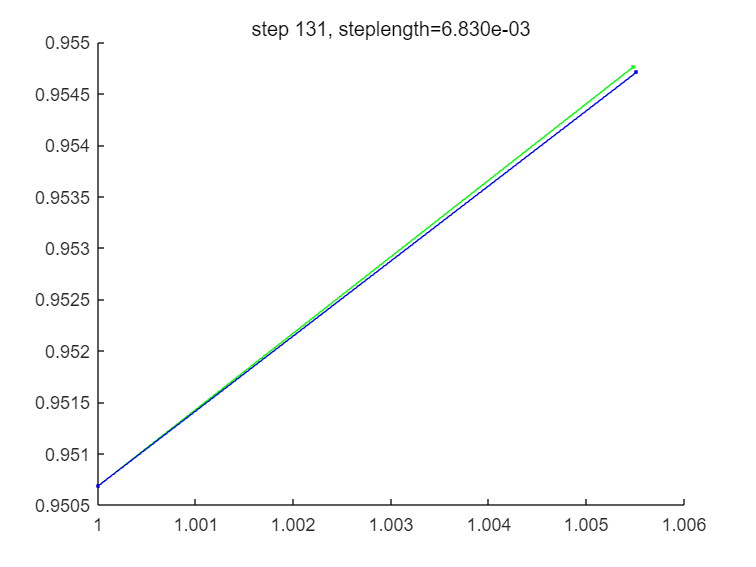


%% 第二部分：固定tau=0.2时的单参数分岔图
% 固定tau参数
tau_fixed = 0.2;
branch_fix = branch1;
% branch_fix.parameter(8:9) = tau_fixed; % 固定tau1=tau2=0.2

% 继续延续
branch_fix = br_contn(funcs,branch_fix,300);


% 检测周期解分支
[hopf_point,~] = LocateSpecialPoints(funcs,branch_fix);

StstCodimension1: calculate stability if not yet present
StstCodimension1: (provisional) 2 fold 2 Hopf  detected.


br_insert: detected 1 of 4: stst. Normalform:
  不包含字段的 struct。
br_insert: discarded 2 of 4 by @(funcs,branch,inds,varargin)Codim1Normalform(funcs,branch,inds,'fold',varargin{:})
Error in @(funcs,branch,inds,varargin)Codim1Normalform(funcs,branch,inds,'fold',varargin{:}):
无法识别的字段名称 "nvec"。

br_insert: discarded 3 of 4 by @(funcs,branch,inds,varargin)Codim1Normalform(funcs,branch,inds,'fold',varargin{:})
Error in @(funcs,branch,inds,varargin)Codim1Normalform(funcs,branch,inds,'fold',varargin{:}):
无法识别的字段名称 "nvec"。



br_insert: detected 4 of 4: stst. Normalform:
  不包含字段的 struct。


无法识别的字段名称 "nvec"。
出错 LocateSpecialPoints (第 61 行)
    if isfield(bifpoints{i},'nvec') && isempty(branch.point(indices(i)).nvec)

if ~isempty(hopf_point)
    % 初始化周期解分支
    [branch_po,~] = SetupPOfold(funcs,branch_fix,hopf_point(1).index);
    branch_po = br_contn(funcs,branch_po,50);
    
    % 计算周期解稳定性
    branch_po = br_stabl(funcs,branch_po,0,0);
end

% 绘制单参数分岔图
figure(6); clf; hold on;

% 绘制平衡点分支
x_P = arrayfun(@(p)p.parameter(ind_P), branch_fix.point);
u_eq = arrayfun(@(p)p.x(1), branch_fix.point);
stability = arrayfun(@(p)max(real(p.stability.l0)), branch_fix.point);

% 稳定平衡点
stable_idx = stability < 0;
plot(x_P(stable_idx), u_eq(stable_idx), 'b-', 'LineWidth', 2);

% 不稳定平衡点
unstable_idx = stability >= 0;
plot(x_P(unstable_idx), u_eq(unstable_idx), 'b--', 'LineWidth', 2);

% 标记分岔点
if ~isempty(hopf_pts)
    plot(hopf_pts(:,1), interp1(x_P, u_eq, hopf_pts(:,1)), 'ro',...
        'MarkerSize',8,'MarkerFaceColor','r');
end
if ~isempty(fold_pts)
    plot(fold_pts(:,1), interp1(x_P, u_eq, fold_pts(:,1)), 'bs',...
        'MarkerSize',8,'MarkerFaceColor','b');
end

% 绘制周期解分支
if exist('branch_po','var')
    po_P = arrayfun(@(p)p.parameter(ind_P), branch_po.point);
    po_u = arrayfun(@(p)mean(p.mesh(1,:)), branch_po.point);
    po_stab = arrayfun(@(p)max(real(p.stability.l0)), branch_po.point);
    
    % 稳定周期解
    stable_po = po_stab < 0;
    plot(po_P(stable_po), po_u(stable_po), 'go', 'MarkerSize',6);
    
    % 不稳定周期解
    unstable_po = po_stab >= 0;
    plot(po_P(unstable_po), po_u(unstable_po), 'gs', 'MarkerSize',6);
end

xlabel('P');
ylabel('u');
title('单参数分岔图 (\tau=0.2)');
legend('稳定平衡点','不稳定平衡点','Hopf分岔','鞍结分岔','稳定周期解','不稳定周期解');
axis([0.4 1 0 1]);
grid on;


function J = neural_deri(xx, par, nx, np, v)
%%
% 完整Wilson-Cowan模型导数函数（数值稳定版）
% 参数顺序: [c1,c2,c3,c4,P,Q,beta,tau1,tau2]
% 状态变量:
%   xx(:,1) - 当前状态 (u(t),v(t))
%   xx(:,2) - τ1延迟 (u(t-τ1),v(t-τ1))
%   xx(:,3) - τ2延迟 (u(t-τ2),v(t-τ2))

% 获取参数
beta = par(7);
c1 = par(1); c2 = par(2); c3 = par(3); c4 = par(4);
P = par(5); Q = par(6);

% 数值稳定的sigmoid计算
sigmoid = @(x) 1./(1 + exp(-min(max(x,-50),50))); % 防止数值溢出

% 预计算激活函数输入项
I_u = c1*xx(1,2) + c2*xx(2,3) + P;
I_v = c3*xx(1,3) + c4*xx(2,2) + Q;

% 计算sigmoid及其导数（数值稳定）
f_u = sigmoid(beta*I_u);
df_u = beta*f_u.*(1 - f_u);
d2f_u = beta^2*f_u.*(1 - f_u).*(1 - 2*f_u);

f_v = sigmoid(beta*I_v);
df_v = beta*f_v.*(1 - f_v);
d2f_v = beta^2*f_v.*(1 - f_v).*(1 - 2*f_v);

J = [];

%% Case 1: 纯状态变量导数
if isempty(np) && isempty(v)
    if isscalar(nx)
        switch nx
            case 0
                J = [-1, 0; 0, -1];
            case 1
                J = [c1*df_u(1), 0;
                     0, c4*df_v(1)];
            case 2
                J = [0, c2*df_u(1);
                     c3*df_v(1), 0];
            otherwise
                error('NEURAL_DERI: 无效索引 nx=%d', nx);
        end
    else
        if numel(nx) ~= 2
            error('NEURAL_DERI: 二阶导数需要2个索引');
        end
        nx1 = nx(1); nx2 = nx(2);
        if nx1 == 0 || nx2 == 0
            J = zeros(2);
        else
            J = zeros(2);
            if nx1 == 1 && nx2 == 1
                J(1,1) = c1^2*d2f_u(1);
                J(2,2) = c4^2*d2f_v(1);
            elseif nx1 == 2 && nx2 == 2
                J(1,2) = c2^2*d2f_u(1);
                J(2,1) = c3^2*d2f_v(1);
            elseif xor(nx1==1, nx2==2)
                J(1,2) = c1*c2*d2f_u(1);
                J(2,1) = c3*c4*d2f_v(1);
            end
        end
    end
    
%% Case 2: 纯参数导数
elseif isempty(nx) && ~isempty(np) && isempty(v)
    J = zeros(2,1);
    switch np
        case 1
            J(1) = xx(1,2)*df_u(1);
        case 2
            J(1) = xx(2,3)*df_u(1);
        case 3
            J(2) = xx(1,3)*df_v(1);
        case 4
            J(2) = xx(2,2)*df_v(1);
        case 5
            J(1) = df_u(1);
        case 6
            J(2) = df_v(1);
        case 7
            J(1) = I_u*f_u(1)*(1-f_u(1));
            J(2) = I_v*f_v(2)*(1-f_v(2));
        case 8 % τ1导数
            J = [-c1*df_u(1)*xx(1,2);  % du/dτ1 = -c1*df_u*u(t-τ1)
                -c4*df_v(1)*xx(2,2)]; % dv/dτ1 = -c4*df_v*v(t-τ1)

        case 9 % τ2导数
            J = [-c2*df_u(1)*xx(2,3);  % du/dτ2 = -c2*df_u*v(t-τ2)
                -c3*df_v(1)*xx(1,3)]; % dv/dτ2 = -c3*df_v*u(t-τ2)
        otherwise
            error('NEURAL_DERI: 无效参数 np=%d', np);
    end
    
%% Case 3: 方向导数（数值稳定处理）
elseif ~isempty(v)
    if numel(nx) ~= 2
        error('NEURAL_DERI: 需要2个导数索引');
    end
    
    nx1 = nx(1); nx2 = nx(2);
    J = zeros(2);
    
    % 排除含即时项的无效组合
    if nx1==0 || nx2==0, return, end
    
    % 核心项计算
    if nx1==1 && nx2==1
        J(1,1) = c1^2*d2f_u(1)*v(1);
        J(2,2) = c4^2*d2f_v(1)*v(2);
    elseif nx1==2 && nx2==2
        J(1,2) = c2^2*d2f_u(1)*v(1);
        J(2,1) = c3^2*d2f_v(1)*v(2);
    elseif (nx1==1 && nx2==2) || (nx1==2 && nx2==1)
        J(1,2) = c1*c2*d2f_u(1)*v(1);
        J(2,1) = c3*c4*d2f_v(1)*v(2);
    end
    
%% Case 4: 混合导数（严格数学推导）
elseif ~isempty(nx) && ~isempty(np)
    J = zeros(2);
    if ~isscalar(nx), return, end
    
    switch nx
        case 0 % 即时导数混合
            if np == 5
                J(1,1) = beta^2*f_u(1)*(1-f_u(1))*(1-2*f_u(1));
            end
            
        case 1 % τ1导数混合
            if np == 1
                J(1,1) = c1*df_u(1) + c1^2*xx(1,2)*d2f_u(1);
            elseif np == 5
                J(1,1) = c1*beta*f_u(1)*(1-f_u(1))*(1-2*f_u(1));
            end
            
        case 2 % τ2导数混合（严格修正）
            if np == 2
                J(1,2) = df_u(1) + c2*xx(2,3)*d2f_u(1);
            elseif np == 3
                J(2,1) = df_v(1) + c3*xx(1,3)*d2f_v(1);
            elseif np == 5
                % 修正：P不直接影响τ2导数，此处应为零
                % 原错误项已移除
            end
            
    end
    
%% Case 5: 边缘情况处理
else
    error('NEURAL_DERI: 未处理类型 nx=%s np=%s v=%s',...
          mat2str(nx), mat2str(np), mat2str(v));
end

% 秩检查（可选）
if matrixRank(full(J)) < min(size(J))
    % warning('NEURAL_DERI: 低秩矩阵 rank=%d', matrixRank(full(J)));
end
end

%% 辅助函数
function r = matrixRank(A)
% 数值稳定的秩计算
tol = max(size(A)) * eps(norm(A));
r = sum(svd(A) > tol);
end